11.10

clc
close all
clear

mot.k = 5.2;
mot.T = 0.03;
pd.Kp = 0.472;
pd.Kd = 0.016;
pd.Tl = 0.004;
Ts = 0.01;
umax = 10;
bit = 10;
res = 2000;

rpm2rads = 2 * pi / 60;
rads2rpm = 60 / (2 * pi);
rad2pulse = res / (2 * pi);
pulse2rad = 2 * pi / res;

z = tf('z', Ts);
s = (1 - z^-1) / Ts;
C2 = minreal(pd.Kd * s / (pd.Tl * s + 1), 1e-6);
[numC2, denC2] = tfdata(C2, 'v');

F = 1 / mot.k;

wc = 2 * pi * 5;
dl = 1 / sqrt(2);
H = minreal(wc^2 * s / (s^2 + 2 * wc * dl * s + wc^2), 1e-6);
[numH, denH] = tfdata(H, 'v');

r.A = 250;
r.t = 0;
d.A = 5;
d.t = 1;

open_system("ex3_sim1m")

set_param("ex3_sim1m", "SolverType", "Variable-Step", "Solver", "ode45", ...
    "MaxStep", "0.0001", "StopTime", "2")
sim("ex3_sim1m")

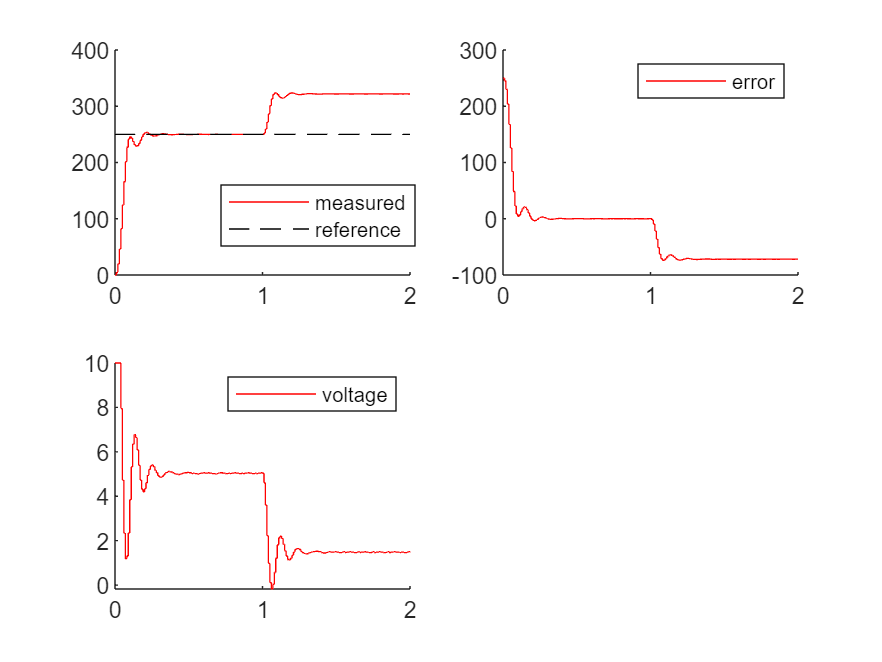

close all
figure(1)
subplot(2, 2, 1)
hold on
stairs(sim1_res.time, sim1_res.signals(1).values, "r")
stairs(sim1_res.time, sim1_res.signals(2).values, "k--")
legend("measured", "reference")

subplot(2, 2, 2)
hold on
stairs(sim1_res.time, sim1_res.signals(3).values, "r")
legend("error")

subplot(2, 2, 3)
hold on
stairs(sim1_res.time, sim1_res.signals(4).values, "r")
legend("voltage")

Come si può notare dal primo grafico, in assenza di disturbi il sistema riesce ad inseguire perfettamente il riferimento, mentre fallisce in presenza del disturbo costante.

pi.Kp = 0.472;
pi.Ki = 3;

open_system("ex3_sim2m")

set_param("ex3_sim2m", "SolverType", "Variable-Step", "Solver", "ode45", ...
    "MaxStep", "0.0001", "StopTime", "2")
sim("ex3_sim2m")

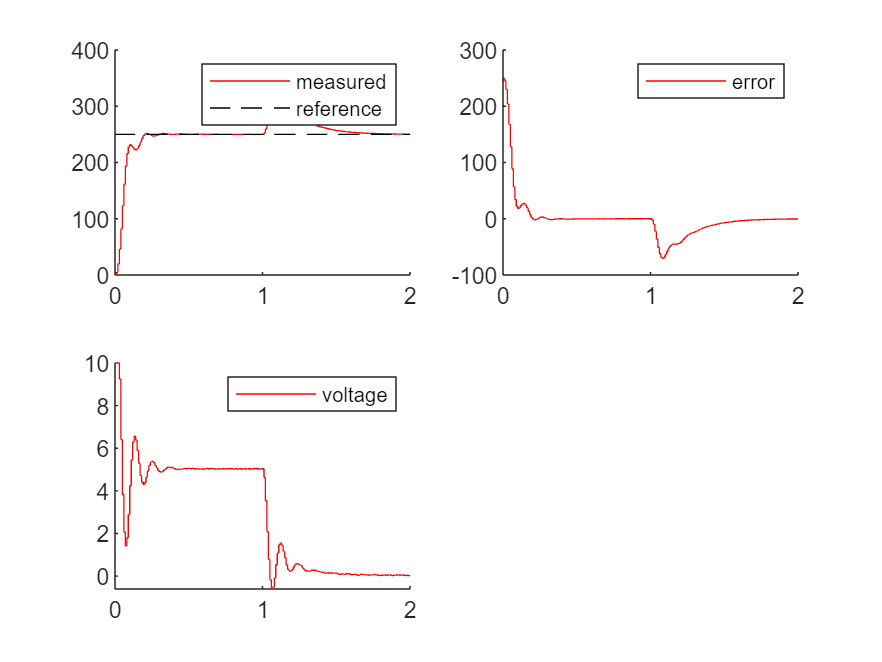

close all
figure(2)
subplot(2, 2, 1)
hold on
stairs(sim2_res.time, sim2_res.signals(1).values, "r")
stairs(sim2_res.time, sim2_res.signals(2).values, "k--")
legend("measured", "reference")

subplot(2, 2, 2)
hold on
stairs(sim2_res.time, sim2_res.signals(3).values, "r")
legend("error")

subplot(2, 2, 3)
hold on
stairs(sim2_res.time, sim2_res.signals(4).values, "r")
legend("voltage")

In questo caso, anche in presenza del disturbo costante, il sistema è in grado di inseguire perfettamente il riferimento costante assegnato.

11.31